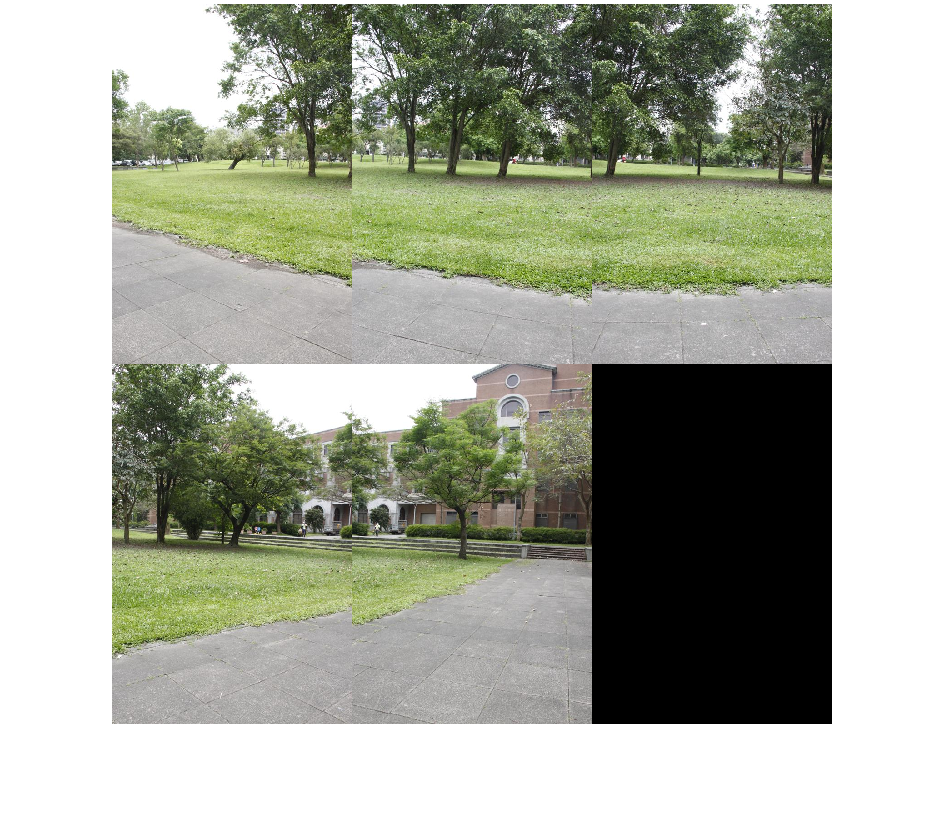

buildingDir = fullfile('check');
buildingScene = imageDatastore(buildingDir);
montage(buildingScene.Files)

xlim([1 721])
ylim([1 721])

I = readimage(buildingScene,1);
grayImage = im2gray(I);
points = detectSURFFeatures(grayImage);
[features, points] = extractFeatures(grayImage,points);
numImages = numel(buildingScene.Files);
tforms(numImages) = projective2d(eye(3));
imageSize = zeros(numImages,2);

for n = 2:numImages
    
    % Store points and features for I(n-1).
    pointsPrevious = points;
    featuresPrevious = features;
        
    % Read I(n).
    I = readimage(buildingScene, n);
    
    % Convert image to grayscale.
    grayImage = im2gray(I);    
    
    % Save image size.
    imageSize(n,:) = size(grayImage);
    
    % Detect and extract SURF features for I(n).
    points = detectSURFFeatures(grayImage);    
    [features, points] = extractFeatures(grayImage, points);
  
    % Find correspondences between I(n) and I(n-1).
    indexPairs = matchFeatures(features, featuresPrevious, 'Unique', true);
       
    matchedPoints = points(indexPairs(:,1), :);
    matchedPointsPrev = pointsPrevious(indexPairs(:,2), :);        
    
    % Estimate the transformation between I(n) and I(n-1).
    tforms(n) = estimateGeometricTransform2D(matchedPoints, matchedPointsPrev,...
        'projective', 'Confidence', 99.9, 'MaxNumTrials', 2000);
    
    % Compute T(n) * T(n-1) * ... * T(1)
    tforms(n).T = tforms(n).T * tforms(n-1).T; 
end

% Compute the output limits for each transform.
for i = 1:numel(tforms)           
    [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 imageSize(i,2)], [1 imageSize(i,1)]);    
end

avgXLim = mean(xlim, 2);
[~,idx] = sort(avgXLim);
centerIdx = floor((numel(tforms)+1)/2);
centerImageIdx = idx(centerIdx);

Tinv = invert(tforms(centerImageIdx));
for i = 1:numel(tforms)    
    tforms(i).T = tforms(i).T * Tinv.T;
end

for i = 1:numel(tforms)           
    [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 imageSize(i,2)], [1 imageSize(i,1)]);
end

maxImageSize = max(imageSize);

% Find the minimum and maximum output limits. 
xMin = min([1; xlim(:)]);
xMax = max([maxImageSize(2); xlim(:)]);

yMin = min([1; ylim(:)]);
yMax = max([maxImageSize(1); ylim(:)]);

% Width and height of panorama.
width  = round(xMax - xMin);
height = round(yMax - yMin);

% Initialize the "empty" panorama.
panorama = zeros([height width 3], 'like', I);

blender = vision.AlphaBlender('Operation', 'Binary mask', ...
    'MaskSource', 'Input port');  

% Create a 2-D spatial reference object defining the size of the panorama.
xLimits = [xMin xMax];
yLimits = [yMin yMax];
panoramaView = imref2d([height width], xLimits, yLimits);

% Create the panorama.
for i = 1:numImages
    
    I = readimage(buildingScene, i);   
   
    % Transform I into the panorama.
    warpedImage = imwarp(I, tforms(i), 'OutputView', panoramaView);
                  
    % Generate a binary mask.    
    mask = imwarp(true(size(I,1),size(I,2)), tforms(i), 'OutputView', panoramaView);
    
    % Overlay the warpedImage onto the panorama.
    panorama = step(blender, panorama, warpedImage, mask);
end

Error using repmat
Requested 37711x147468 (41.4GB) array exceeds maximum array size preference (16.0GB). This might cause MATLAB to become
unresponsive.

Error in meshgrid (line 61)
        xx = repmat(xrow,size(ycol));

Error in images.geotrans.internal.getSourceMappingInvertible2d (


figure
imshow(panorama)